# Power-Split Drive Unit Model - Main Script

## Open Model and Run Simulation

mdl = "PowerSplitDriveUnit_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

% Load default parameters
PowerSplitDriveUnit_harness_setup

% Set up external input signals
PSDU_SignalBuilder = PowerSplitDriveUnit_InputSignalBuilder;
inputPatterns = [
  "Input_Constant"
  "DriveFromAxle"
  "DriveWithMG2"
  "DriveWithMG1"
  "DriveWithMG1_LockAxle"
  "StartEngineWithMG1_ThenSplitPower"
];
numSim = numel(inputPatterns);

% Create SimulationInput object for each simulation
%simIn(1:numSim) = Simulink.SimulationInput(mdl);  % error in R2022a.
simIn(1:numSim) = Simulink.SimulationInput(char(mdl));
for idx = 1 : numSim
  InpData = feval(inputPatterns(idx), PSDU_SignalBuilder);
  simIn(idx) = setVariable(simIn(idx), "PSDU_InputSignals", InpData.Signals);
  simIn(idx) = setVariable(simIn(idx), "PSDU_InputBus", InpData.Bus);
  simIn(idx) = setModelParameter(simIn(idx), "StopTime",num2str(InpData.Options.StopTime_s));
end

% Run simulations
simOut = sim(simIn, "UseFastRestart","on", "ShowProgress","on");

[08-Apr-2022 13:32:07] Running simulations...
[08-Apr-2022 13:32:13] Completed 1 of 6 simulation runs
[08-Apr-2022 13:32:14] Completed 2 of 6 simulation runs
[08-Apr-2022 13:32:14] Completed 3 of 6 simulation runs
[08-Apr-2022 13:32:15] Completed 4 of 6 simulation runs
[08-Apr-2022 13:32:16] Completed 5 of 6 simulation runs
[08-Apr-2022 13:32:16] Completed 6 of 6 simulation runs


## Simulation Results

Input_Constant


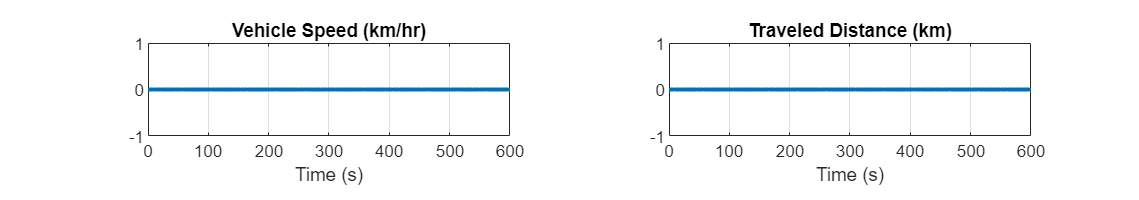

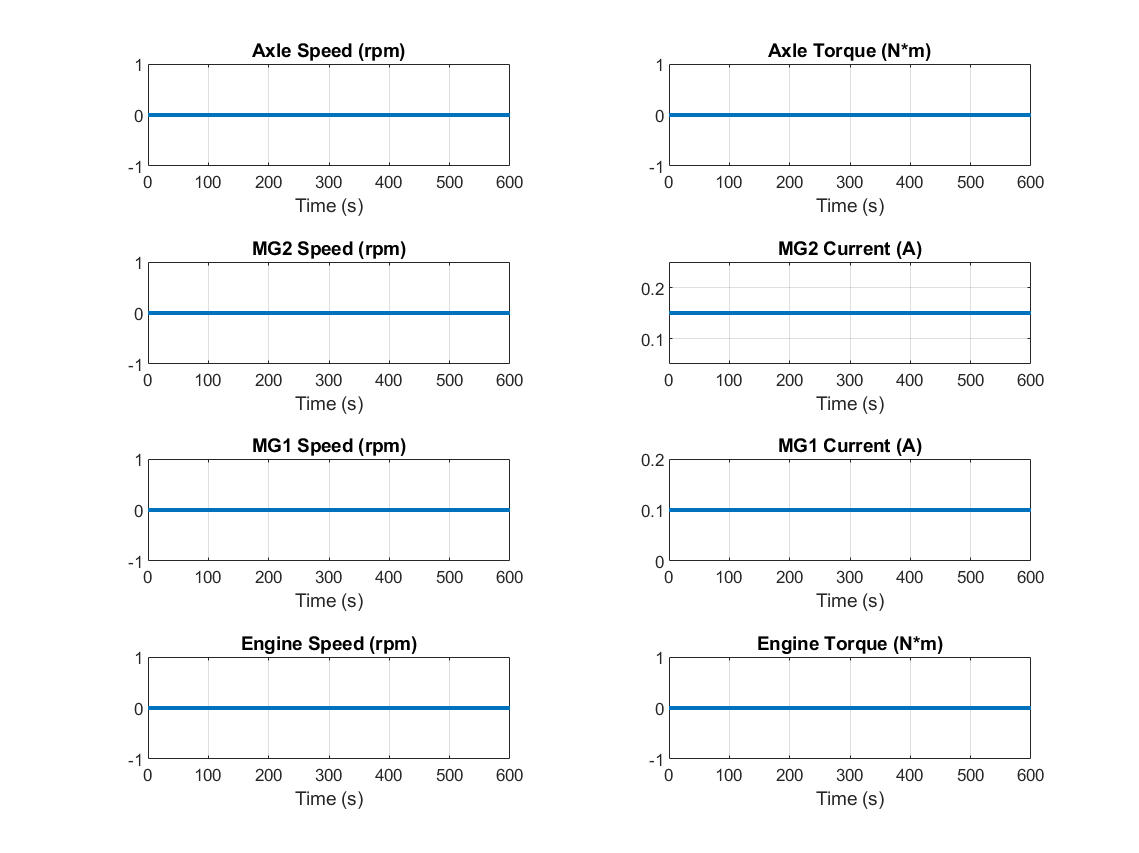

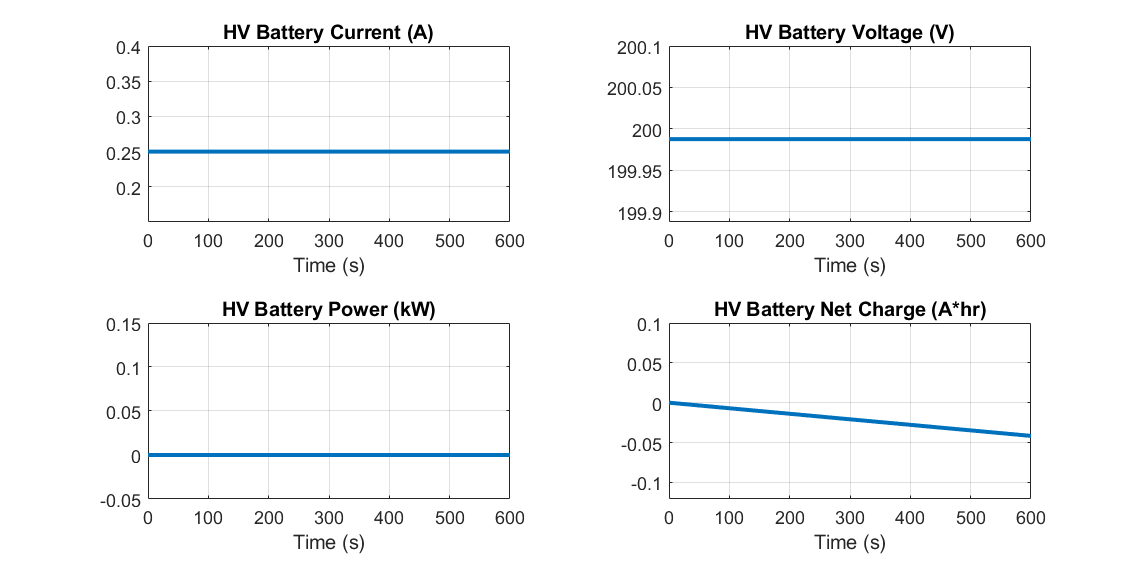

DriveFromAxle


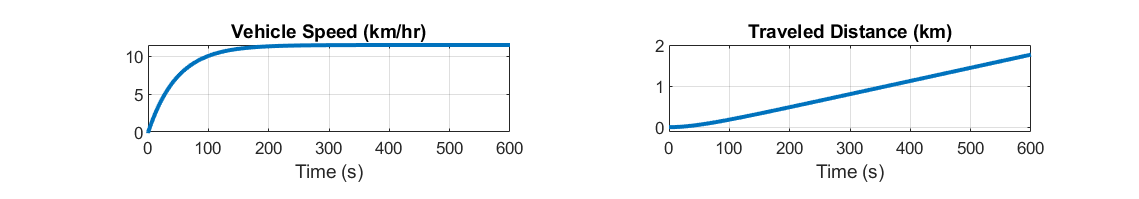

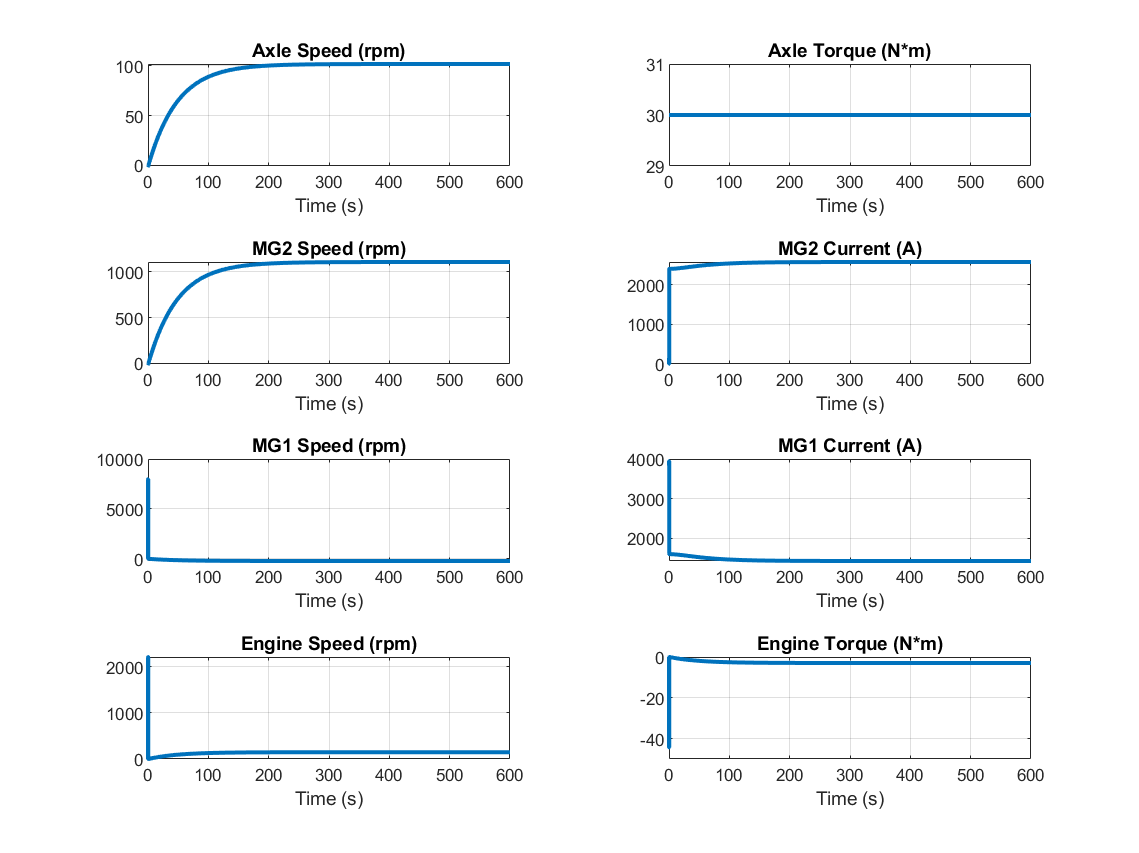

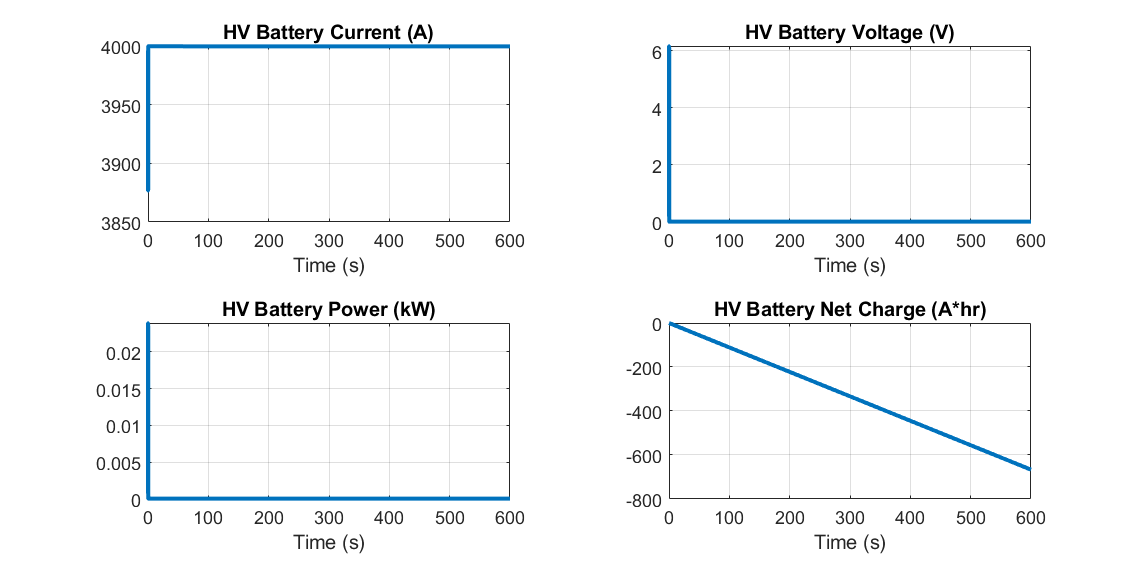

DriveWithMG2


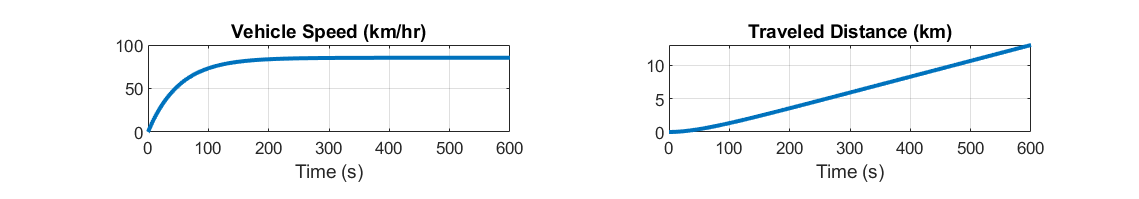

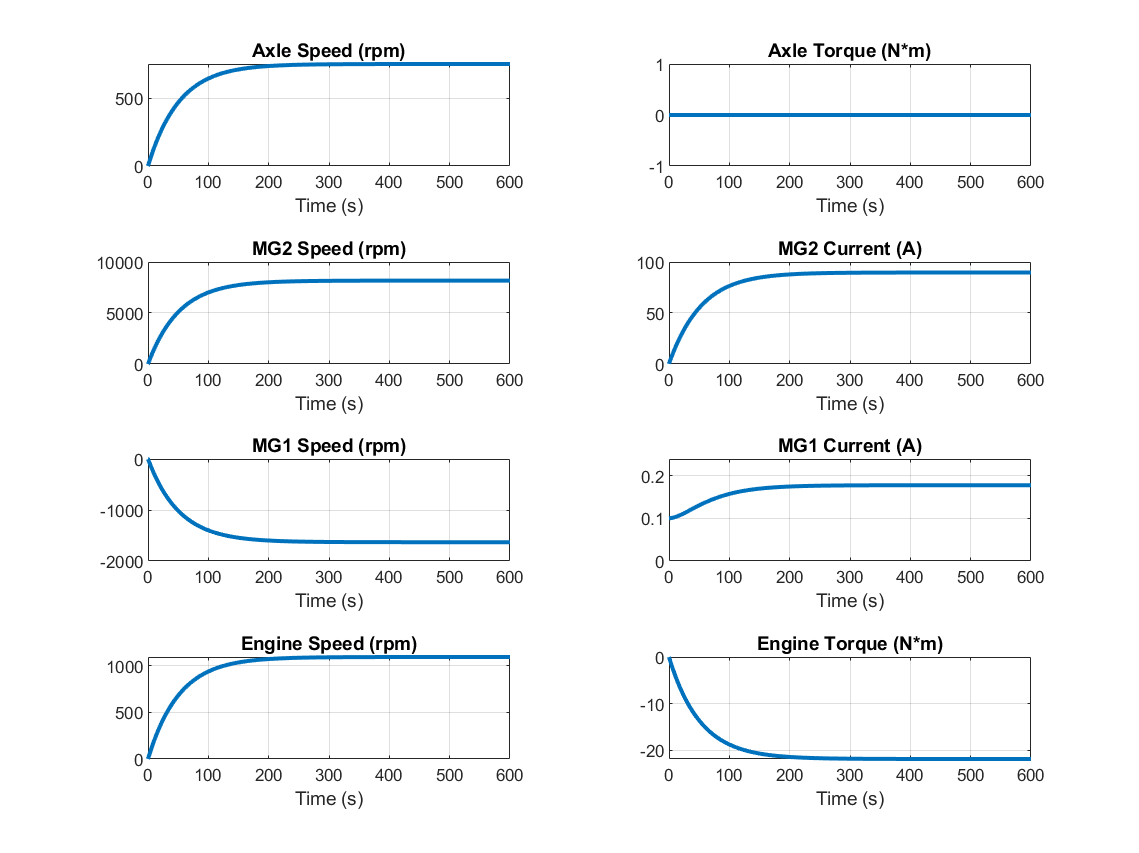

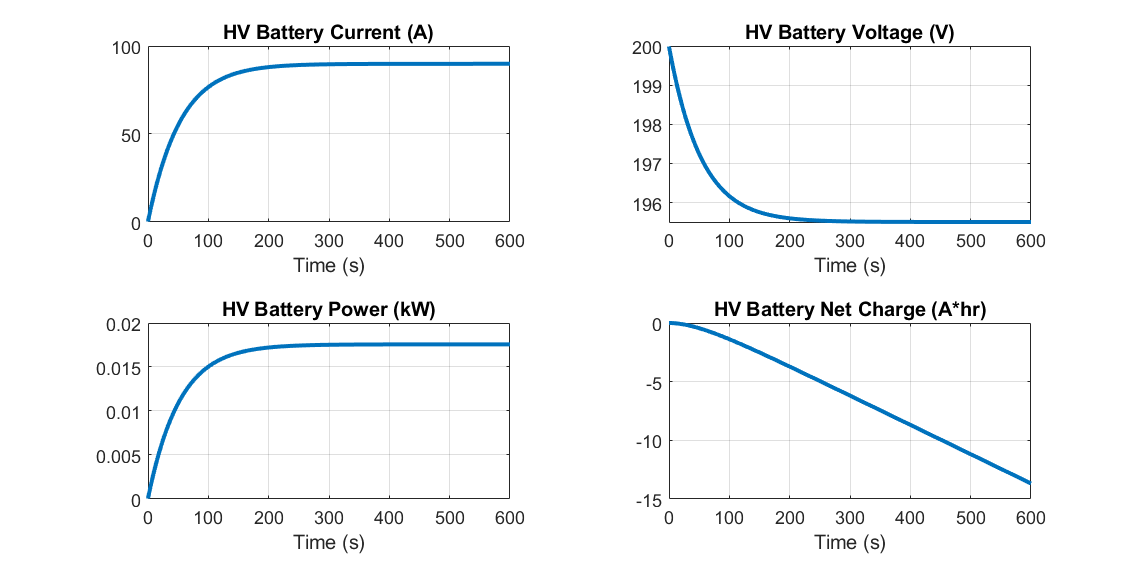

DriveWithMG1


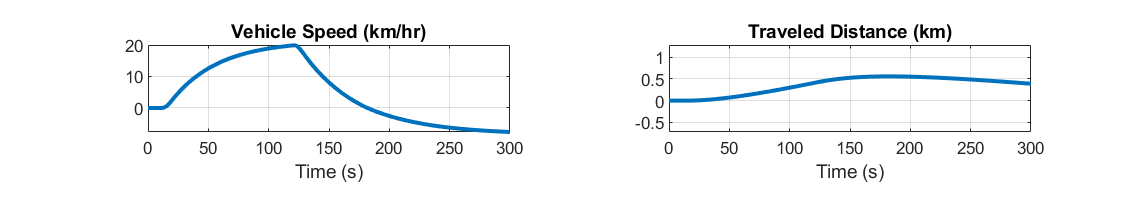

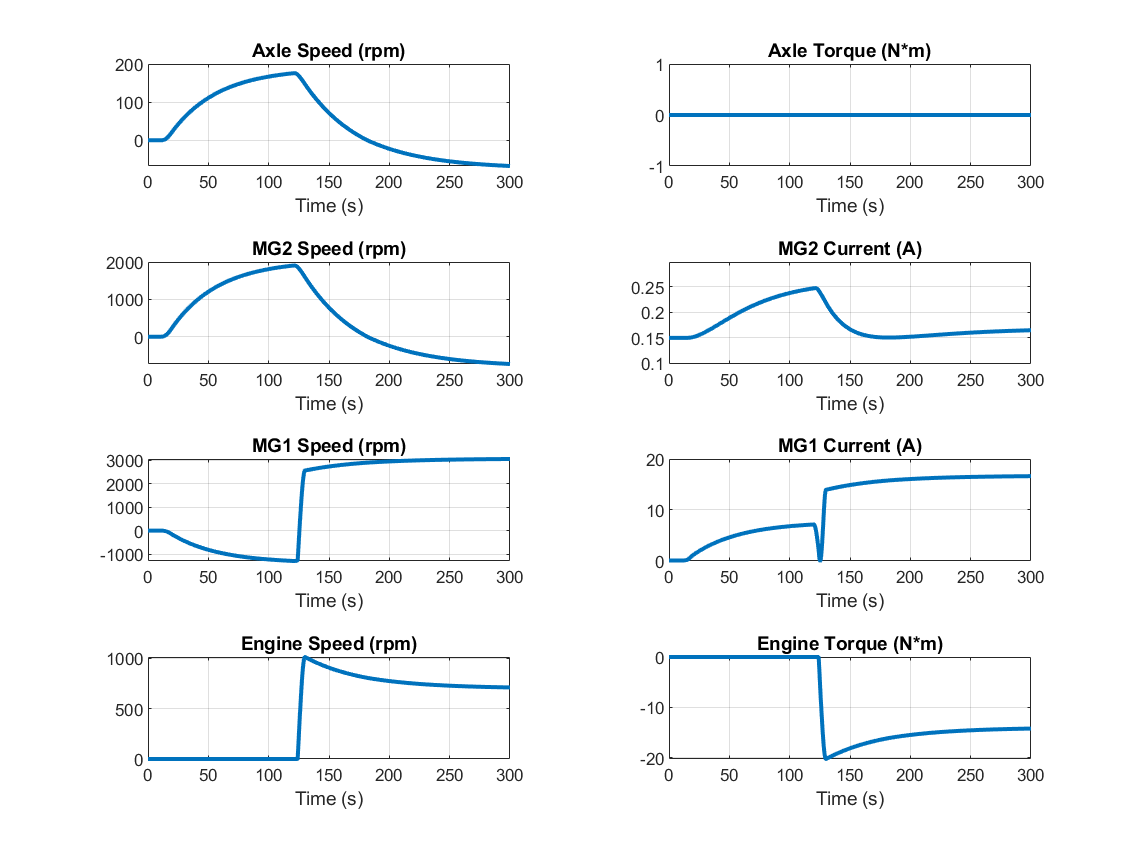

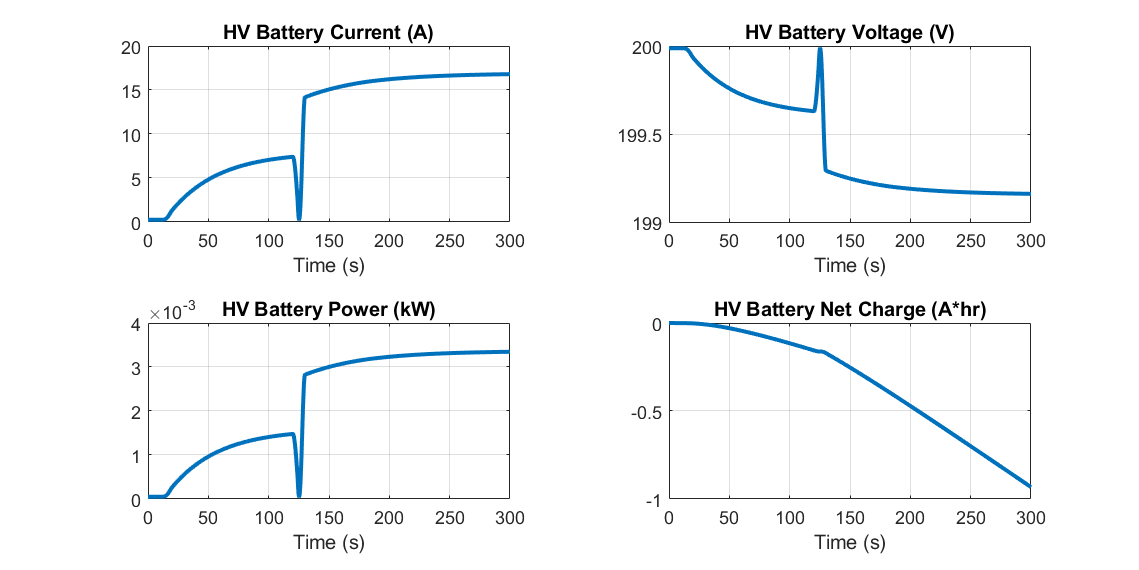

DriveWithMG1_LockAxle


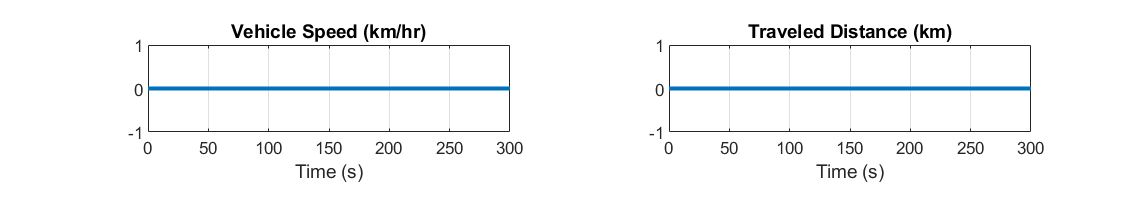

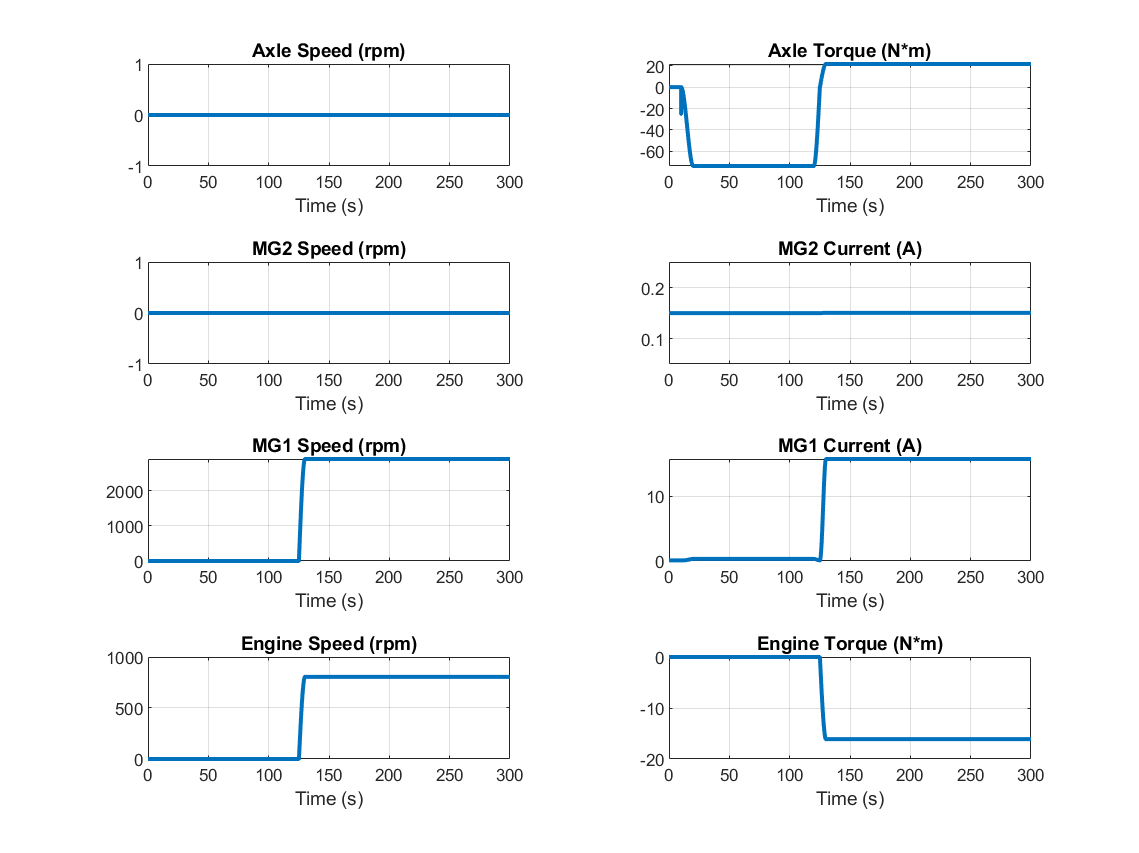

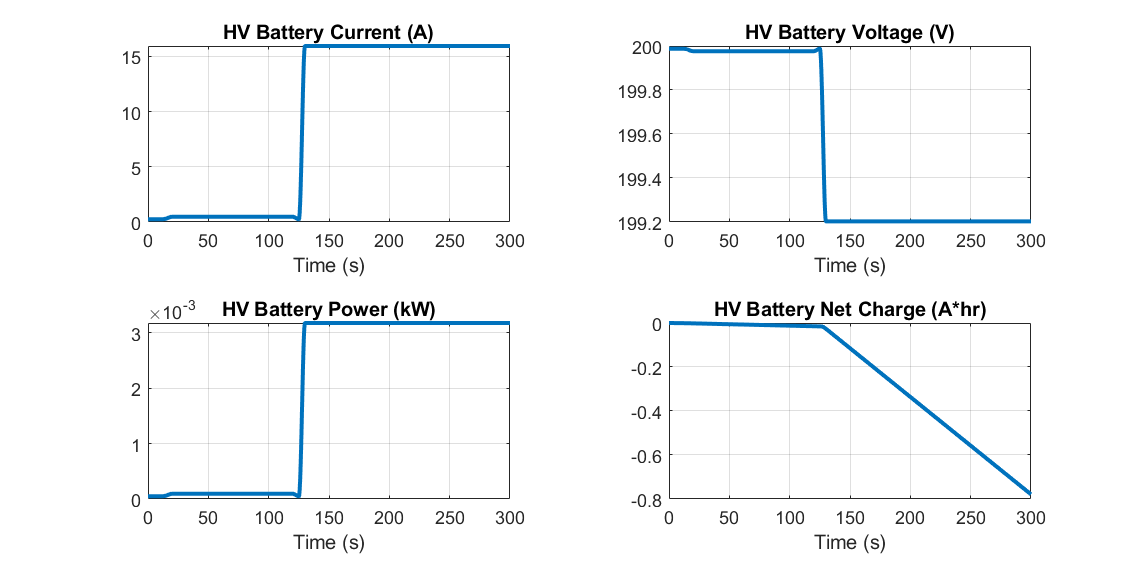

StartEngineWithMG1_ThenSplitPower


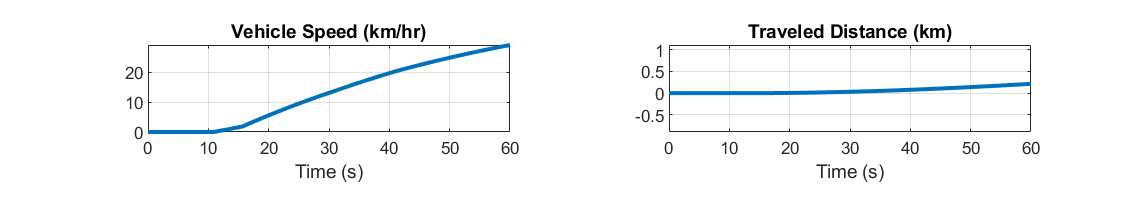

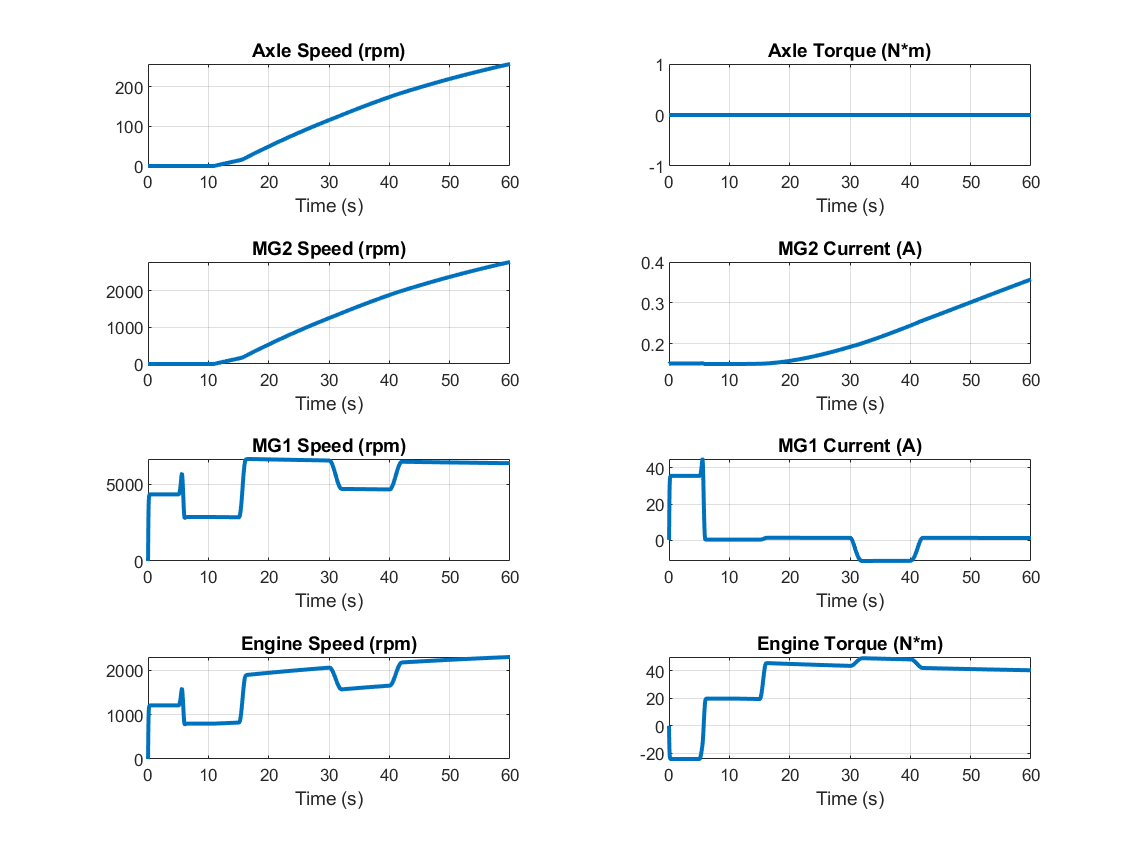

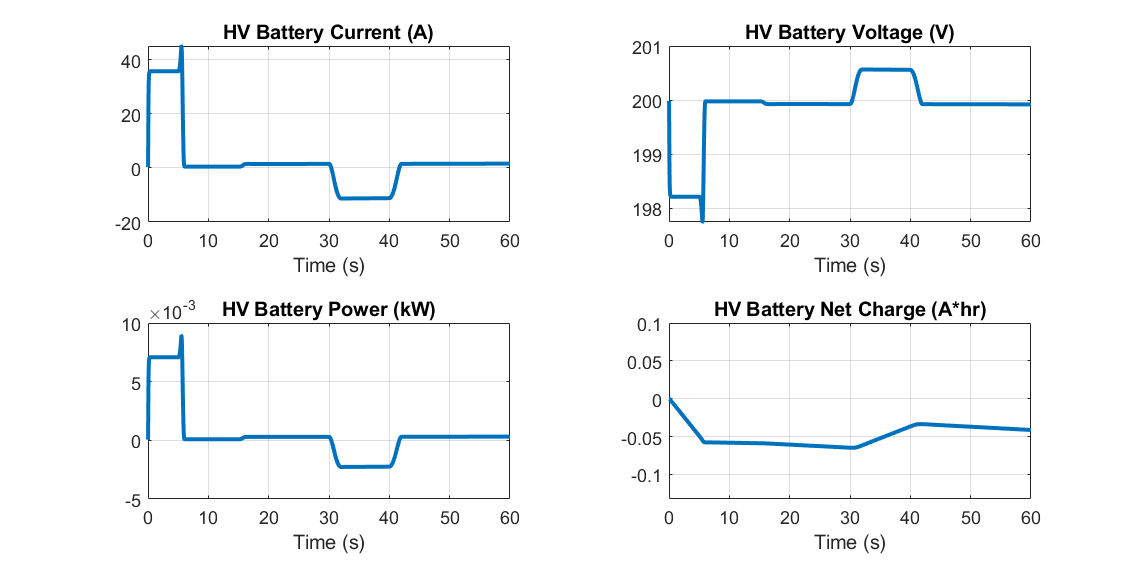

for idx = 1 : numSim
  disp(inputPatterns(idx))
  PowerSplitDriveUnit_plot_results(simOut(idx).logsout)
end

*Copyright 2021-2022 The Mathworks, Inc.*